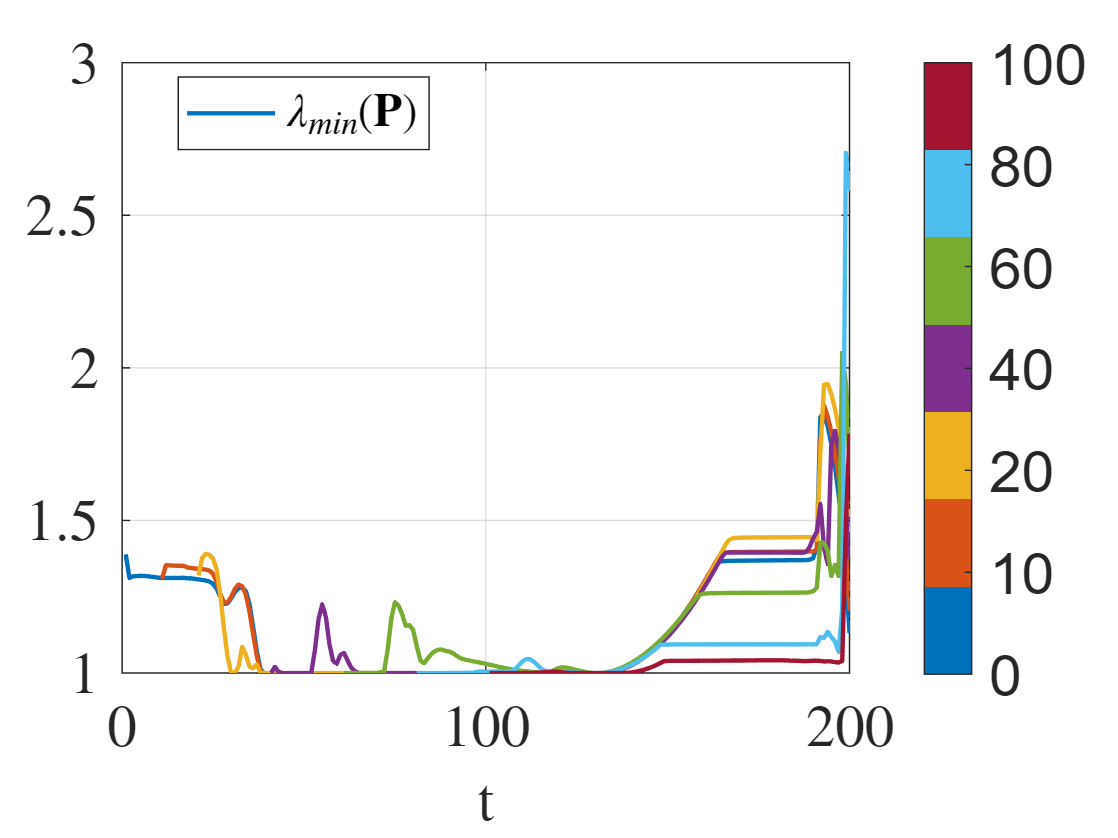

figure;
hold on;
cmap = lines(length(t0));  % Colormap with 9 colors (one per t0 value)
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex','FontSize',20);
% Plot each curve with color based on t0 value
for j3 = 1:length(t0)
    if ~isempty(all_eigenvalues{j3})
        time_points = t0(j3)+(1:length(all_eigenvalues{j3}))*dt;
        min_eig = cellfun(@min, all_eigenvalues{j3});
        max_eig = cellfun(@max, all_eigenvalues{j3});
        plot(time_points, min_eig, 'Color', cmap(j3,:), 'LineWidth', 1.5);
%         semilogy(time_points, max_eig, '--', 'Color', cmap(j3,:), 'LineWidth', 1.5);
    end
end

% Configure colorbar with exact t0 values
c = colorbar;
colormap(cmap);

% Set discrete ticks at centers of each color segment
c.Ticks = linspace(0, 1, length(t0));  % 9 ticks from 0 to 1
c.TickLabels = arrayfun(@(x) num2str(x), t0, 'UniformOutput', false);  % Exact t0 values
c.FontSize = 20; % Larger colorbar numbers

legend({'$\lambda_{min}(\mathbf{P})$'}, 'Location', 'best','Interpreter', 'latex','FontSize',16);

% Axis labels and formatting
xlabel('t','FontSize',20);
% ylabel('Eigenvalue of \boldsymbol{P}');
grid on;
box on;
hold off;

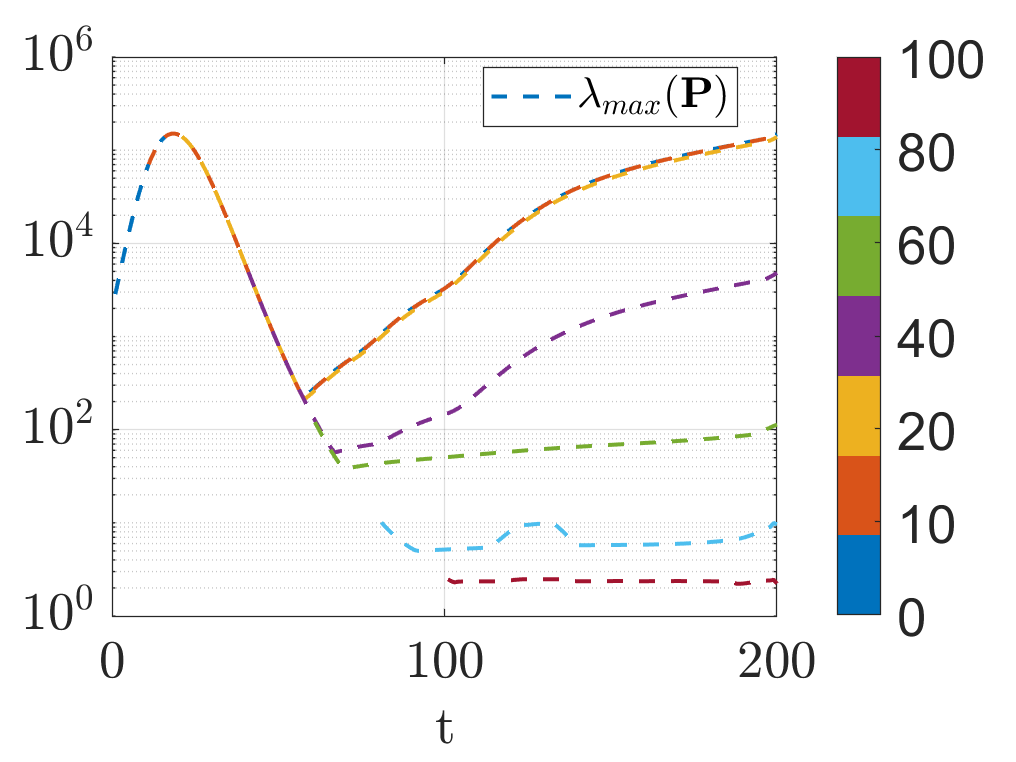



figure;
hold on;
cmap = lines(length(t0));  % Colormap with 9 colors (one per t0 value)
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize',20);
% Plot each curve with color based on t0 value
for j3 = 1:length(t0)
    if ~isempty(all_eigenvalues{j3})
%         time_points = t0(j3) + (1:length(all_eigenvalues{j3}))*dt;
        time_points = t0(j3)+(1:length(all_eigenvalues{j3}))*dt;
        min_eig = cellfun(@min, all_eigenvalues{j3});
        max_eig = cellfun(@max, all_eigenvalues{j3});
%         semilogy(time_points, min_eig, 'Color', cmap(j3,:), 'LineWidth', 1.5);
        plot(time_points, max_eig, '--', 'Color', cmap(j3,:), 'LineWidth', 1.5);
    end
end

% Configure colorbar with exact t0 values
c = colorbar;
colormap(cmap);
c.FontSize = 20; % Larger colorbar numbers

% Set discrete ticks at centers of each color segment
c.Ticks = linspace(0, 1, length(t0));  % 9 ticks from 0 to 1
c.TickLabels = arrayfun(@(x) num2str(x), t0, 'UniformOutput', false);  % Exact t0 values

legend({'$\lambda_{max}(\mathbf{P})$'}, 'Location', 'best','Interpreter', 'latex', 'FontSize', 16);
set(gca,'yscale','log');
% Axis labels and formatting
xlabel('t','FontSize', 20);
% ylabel('Eigenvalue of \boldsymbol{P}');
grid on;
box on;
hold off;